# Clutter Modeling

clc
close all
clearvars

## Constants

c = physconst("lightspeed");
fc = 9.5e9;

## Define Clutter Reflectivity

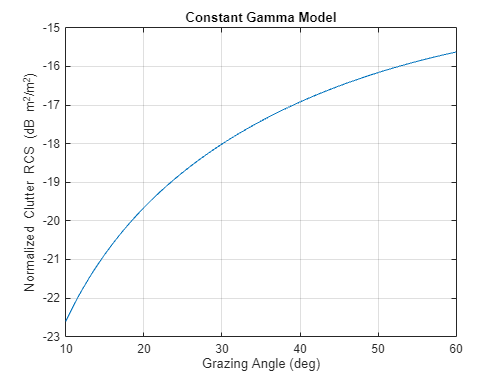

% Compute gamma parameter for Farmland area
gammaValue = surfacegamma("Farmland");
% Compute normalized surface reflectivity
sigmaZero = surfaceReflectivityLand("Model","ConstantGamma","Gamma",gammaValue);

grazingAng = 10:60;
% Visualize reflectivity change with respect to grazing angle
normClutterRCS = sigmaZero(grazingAng,fc);
plot(grazingAng,pow2db(normClutterRCS))
grid on
xlabel("Grazing Angle (deg)")
ylabel("Normalized Clutter RCS (dB m^2/m^2)")
title("Constant Gamma Model")

## Define Scenario

scenario = radarScenario("IsEarthCentered",false);

## Add Land Surface to Scenario

landSurface(scenario,"RadarReflectivity",sigmaZero,"Boundary",[4000 8000; -1000 1000]);

## Define Radar

rdr = radarTransceiver("MountingAngles",[-90 40 0]);
rdr.Waveform = phased.RectangularWaveform("DurationSpecification","Duty cycle","DutyCycle",0.04);
rdr.ReceiveAntenna.OperatingFrequency = fc;
rdr.TransmitAntenna.OperatingFrequency = fc;
rdr.TransmitAntenna.Sensor = phased.ULA(4,"Element",phased.CosineAntennaElement); % phased.CosineAntennaElement; % 
rdr.ReceiveAntenna.Sensor = phased.ULA(4,"Element",phased.CosineAntennaElement); % phased.CosineAntennaElement; % 
rdr.TransmitAntenna.Sensor.ElementSpacing = freq2wavelen(fc) / 2;
rdr.ReceiveAntenna.Sensor.ElementSpacing = freq2wavelen(fc) / 2;
rdr.Transmitter.PeakPower = 1e3;
rdr.NumRepetitions = 16;

## Add airborn platform

vel = [0 250 0];
radarPlatform = platform(scenario);
radarPlatform.Trajectory = kinematicTrajectory("Position",[0 0 500],"Velocity",vel,"Orientation",rotz(90).');
radarPlatform.Sensors{1} = rdr;

## Add Clutter Generation for Radar and Scene

clut = clutterGenerator(scenario,rdr);

## Set up processors

mFilter = rdr.Waveform.getMatchedFilter();
% steering vector
strVec = phased.SteeringVector("SensorArray",rdr.TransmitAntenna.Sensor,"PropagationSpeed",c);
% range processor
rdProcessor = phased.RangeDopplerResponse("RangeMethod","Matched filter","SampleRate",rdr.Waveform.SampleRate,"DopplerOutput","Speed");

## Receive IQ Signal

recSig = receive(scenario);

## Apply Angle Processor

angProcessed = squeeze(pagemtimes(recSig{1,1}, strVec(fc,0)));

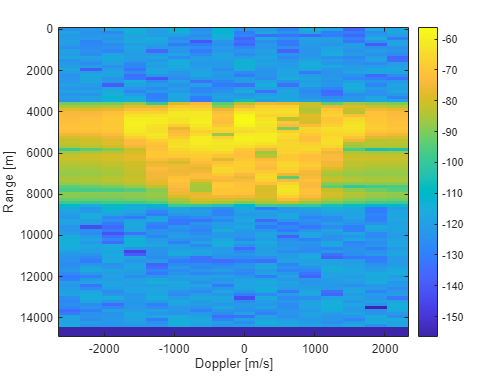

[resp,rng_grid,dop_grid] = rdProcessor(angProcessed,mFilter);
imagesc(dop_grid,rng_grid,mag2db(abs(resp)))
xlabel("Doppler [m/s]")
ylabel("Range [m]")
colorbar

## Display Clutter Patch

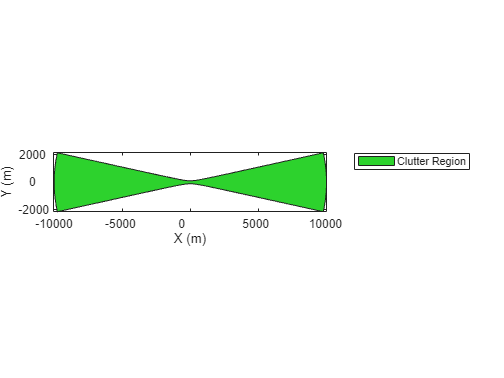

tp = theaterPlot;
clutPlotter = clutterRegionPlotter(tp,"DisplayName","Clutter Region");
plotClutterRegion(clutPlotter,clutterRegionData(clut));

landSurface(scenario,...
"RadarReflectivity",sigmaZero);